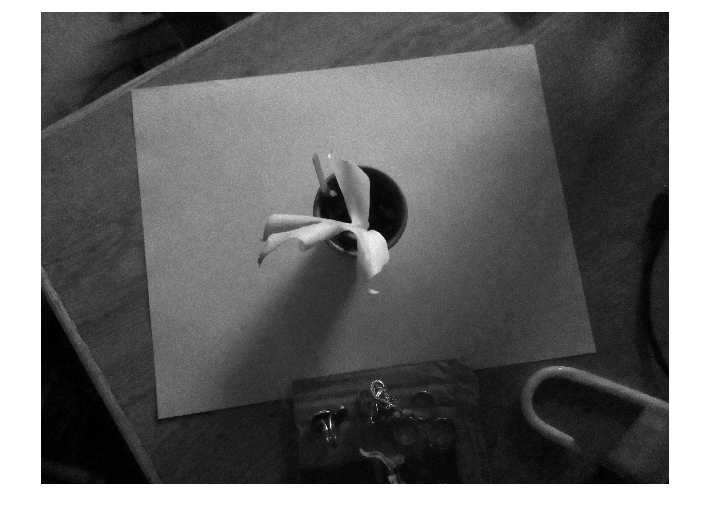

f = imread("blupassbad.jpg");
%f = f(800:1400,1400:1900,:)
%imshow(f);

fr = f(:,:,1);

%imshow(fr)


n = imread("fullpassbad.jpg");
%n = n(800:1400,1300:1800,:)
%imshow(n);

nr = n(:,:,1);

%ng = n(:,:,3);
%ng = ng(600:1600,1000:2000,:);

r = nr - fr;
fr = fr*2;
imshow(fr)

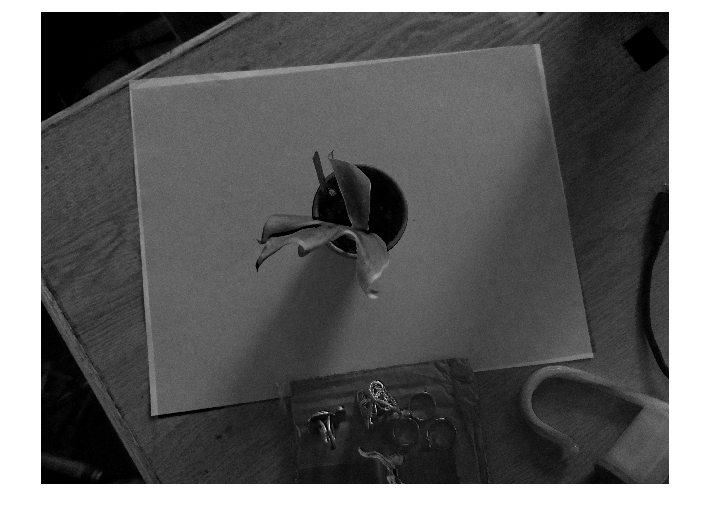

imshow(r)

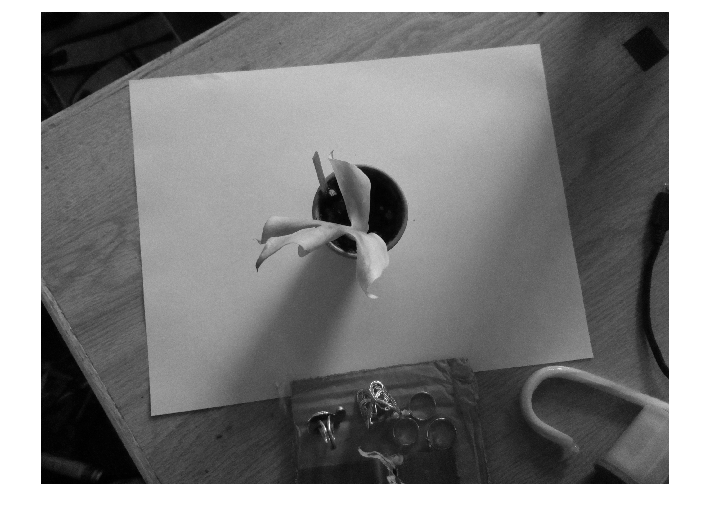

imshow(nr)

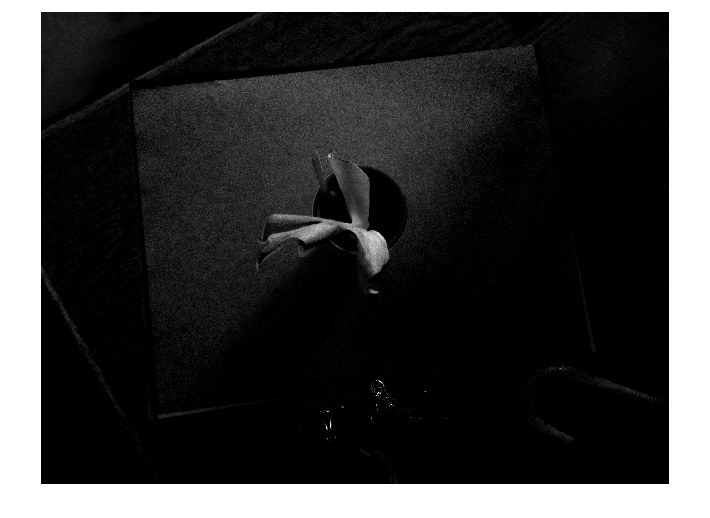

%imshow(ng)

nir = im2single(fr);
red = im2single(r);

ndvi = ((nir-red)./((nir+red).^(-1)));
imshow(ndvi)








ex = imread("fullpassoutline.png")

ex = 2464×3280×3 uint8 array
ex(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

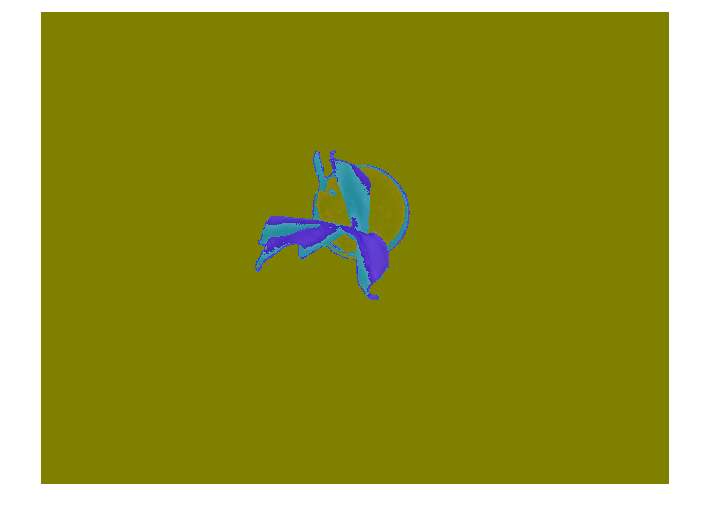

%ex = ex(600:1600,1000:2000,:)
ex = im2single(ex);
numColors = 3;
pixel_labels = imsegkmeans(ex,numColors,NumAttempts=3);
B2 = labeloverlay(ex,pixel_labels);
imshow(B2)

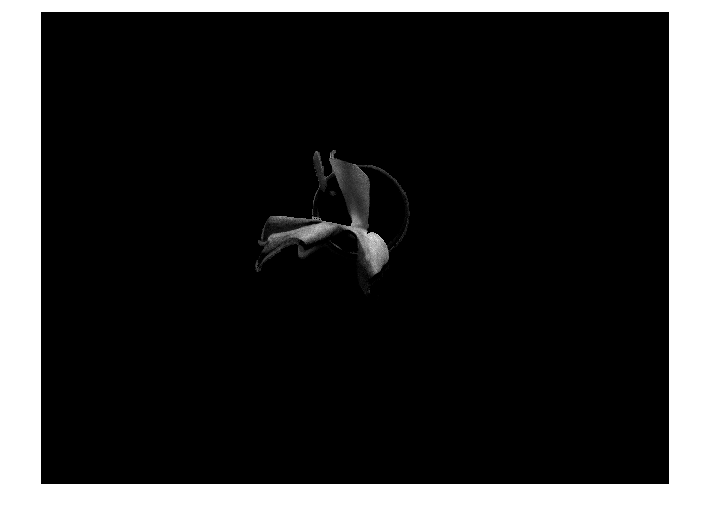


mask2 = pixel_labels == 2; 
ndvic1 = ndvi.*mask2;

mask3 = pixel_labels == 3; %set mask for each group
ndvic2 = ndvi.*mask3;

B3 = ndvic1 + ndvic2;
imshow(B3);


sz = size(B3);
znv = reshape(B3,sz(1)*sz(2),1);
nv = nonzeros(znv);
average = mean(nv)

average = single
0.2381



%st = [0 0 0, 0 2 0, 0 0 0]
%fst = imfilter(f,st)
%e = [ 0 -3 0,-3 12 -3, 0, -3, 0];
%fedge = imfilter(fst,e)
%imshow (fedge);